# ปัญหาวันที่ 2

## เป้าหมาย

- สามารถระบุตำแหน่งของ stamping event ได้

- สามารถจำแนก stamping event ได้ (N/F)

- สามารถอธิบายแนวทางในการหาตำแหน่ง event การตัด segment และการจำแนก event ได้

## ข้อกำหนด

- ใช้ไฟล์ที่อยู่ใน folder Day2 ในการ train model โดยต้องตัดเองและเลือกความยาวในการตัดเอง

## ผลลัพธ์ที่ต้องการ

- โปรแกรมจะอ่านไฟล์ที่กำหนด แล้วแสดงผลลัพธ์เป็นตำแหน่งของ event และสถานะเป็น N (normal) หรือ F (faulty) บรรทัดละ event

- ตำแหน่งของ event จะเป็นลำดับของ sample นับตั้งแต่พบสัญญาณ SYNC โดยอนุญาตให้คลาดเคลื่อนได้ +/- 14400 sample (0.3 วินาที)

- รูปแบบการแสดงผลคล้ายดังนี้

102230 N

197740 F

275941 F

...

## โครงโปรแกรม

สามารถเขียนใหม่ได้ทั้งหมด ไม่จำเป็นต้องใช้ตามนี้

ตอนตรวจขั้นสุดท้าย จะต้องเปลี่ยนชื่อไฟล์ด้านล่างนี้ให้เป็นไฟล์ที่กำหนด

# ปัญหาวันที่ 2

## เป้าหมาย

- สามารถระบุตำแหน่งของ stamping event ได้

- สามารถจำแนก stamping event ได้ (N/F)

- สามารถอธิบายแนวทางในการหาตำแหน่ง event การตัด segment และการจำแนก event ได้

## ข้อกำหนด

- ใช้ไฟล์ที่อยู่ใน folder Day2 ในการ train model โดยต้องตัดเองและเลือกความยาวในการตัดเอง

## ผลลัพธ์ที่ต้องการ

- โปรแกรมจะอ่านไฟล์ที่กำหนด แล้วแสดงผลลัพธ์เป็นตำแหน่งของ event และสถานะเป็น N (normal) หรือ F (faulty) บรรทัดละ event

- ตำแหน่งของ event จะเป็นลำดับของ sample นับตั้งแต่พบสัญญาณ SYNC โดยอนุญาตให้คลาดเคลื่อนได้ +/- 14400 sample (0.3 วินาที)

- รูปแบบการแสดงผลคล้ายดังนี้

102230 N

197740 F

275941 F

...

## โครงโปรแกรม

สามารถเขียนใหม่ได้ทั้งหมด ไม่จำเป็นต้องใช้ตามนี้

ตอนตรวจขั้นสุดท้าย จะต้องเปลี่ยนชื่อไฟล์ด้านล่างนี้ให้เป็นไฟล์ที่กำหนด

load("model.mat")


results = {}; % Create an empty cell array to store results
rowIndex = 1; % Initialize a row index for saving data

frameLength = 256;

% Using dsp.AudioFileReader
fileReader = dsp.AudioFileReader('Day2\Normal1.wav', 'SamplesPerFrame', frameLength);
Fs = fileReader.SampleRate;

deviceWriter = audioDeviceWriter('SampleRate', Fs); % ส่งออกทีละ frame

scope = timescope('SampleRate', Fs, 'TimeSpan', 2, 'BufferLength', Fs * 2, ...
                  'YLimits', [0, 0.3], 'TimeSpanOverrunAction', 'scroll');

bufferLength = round(5.0 * Fs);
audioBuffer = zeros(1, bufferLength);
bufferPosition = 1;
audioPositionSinceSync = 1;

maxPeak = 0.0;
startThreshold = db2mag(-30);

% Wait for SYNC signal (sinusoid with amplitude larger than -30 dBFS)
while ~isDone(fileReader)
    signal = fileReader(); % read a new frame
    if max(signal) > startThreshold
        maxPeak = max(signal);
        break;
    end
end

while ~isDone(fileReader)
    signal = fileReader(); % read a new frame

    % Adaptive normalization (-1, 1)
    signalPeak = max(abs(signal));
    if signalPeak > maxPeak
        maxPeak = signalPeak;
    end
    signal = signal / maxPeak; % scale the signal towards 1.0

    % Handle audio buffer
    frameLength = length(signal);
    emptyLength = bufferLength - bufferPosition + 1;
    % Make space for the new frame 
    if emptyLength < frameLength
        moveOffset = frameLength - emptyLength;
        audioBuffer(1:bufferPosition-moveOffset-1) = audioBuffer(moveOffset+1:bufferPosition-1);
        bufferPosition = bufferPosition - moveOffset;
    end
    % Fill in the buffer with the new frame
    audioBuffer(bufferPosition:bufferPosition+frameLength-1) = signal;
    bufferPosition = bufferPosition + frameLength;
    audioPositionSinceSync = audioPositionSinceSync + frameLength;

    % Process audio in the buffer (event detection)
    shortWinLength = round(0.3 * Fs);
    shortRMS = dsp.MovingRMS(shortWinLength);

    env1 = shortRMS(signal);
    threshold1 = mean(env1) + 1.99 * std(env1);
    peakIndices = find(env1 > threshold1);
    audioFFT = abs(fft(signal, 512))';

    % Segment, classify, and report results
    if ~isempty(peakIndices)
        fprintf("%s \n", num2str(audioPositionSinceSync));

    end

    % deviceWriter(signal);
    scope(env1);
    % scope(mag2db(env1));
end

34049 
54529 
56065 
59905 
125185 
143873 
199937 
278017 
288001 
293121 
295169 
298753 
300801 
302593 
312577 
377345 
383489 
507137 
542977 
585473 
590337 
594689 
701953 
712705 
744449 
835073 
843777 
984833 
990721 
998145 
1007873 
1011457 
1030657 
1047553 
1075969 
1208065 
1230849 
1234945 
1246209 
1250561 
1298433 
1431809 
1435393 
1442561 
1444353 
1467393 
1496321 
1537281 
1612801 
1622529 
1635329 
1639937 
1641729 
1679361 
1713153 
1717505 
1762561 
1785089 
1949953 
1995265 
2006529 
2013697 
2021121 
2029825 
2064641 
2075137 
2135297 
2224129 
2241793 
2245377 
2322689 
2341377 
2342913 
2480641 
2499585 
2539265 
2547713 
2649089 
2653185 
2691841 
2697729 
2717441 
2727937 
2730241 
2736641 
2784001 
2789121 
2811649 
2815745 
2867713 
2897153 
2915585 
2934785 
2935297 
2968833 
3031809 
3119361 
3188737 
3208449 
3209985 
3222529 
3259649 
3260161 
3361793 
3414017 
3416065 
3420673 
3420929 
3428353 
3442689 
3444993 
3447041 
3464449 
3502337 
3509249 

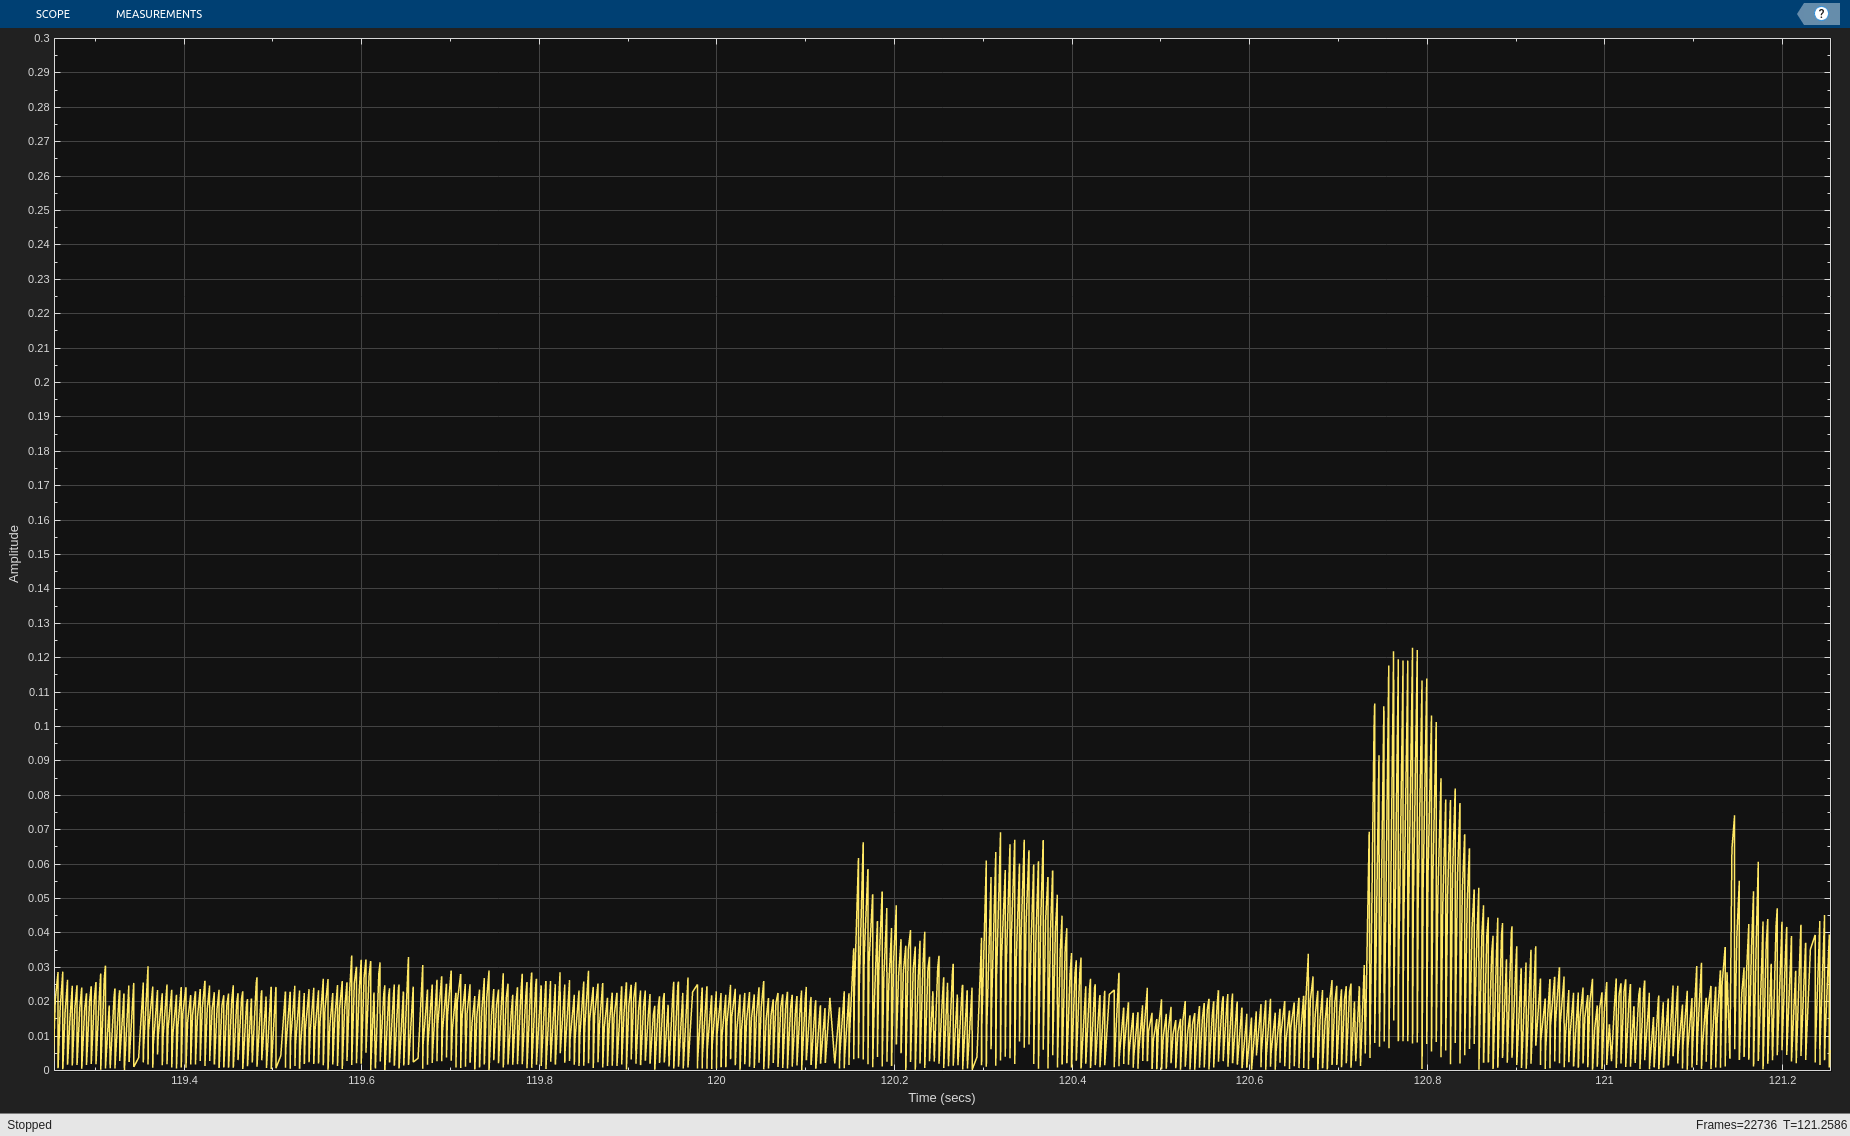


% resultsTable = cell2table(results, 'VariableNames', {'Stamping Event', 'Predicted'});
% writetable(resultsTable, 'predictions.xlsx'); % Save as predictions.xlsx

release(scope);

release(fileReader);
% release(deviceReader);
release(deviceWriter);